# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2023b on 07-Mar-2024 12:33:15

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("macvideo", 1, "YCbCr422_320x240");

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";

## Configure File Logging

Configure the device to log video to disk. Set the desired file location and name.

filelocation = "/Users/maciekadamus/Documents/MATLAB/interfejsy_multimodalne/lab02";
filename = "testVideo1.avi";
fullFilename = fullfile(filelocation, filename);

% Create and configure the video writer
logfile = VideoWriter(fullFilename, "Motion JPEG AVI");

% Configure the device to log to disk using the video writer
v.LoggingMode = "disk";
v.DiskLogger = logfile;

## Record Video for Set Number of Seconds

Record video data for a specified period of time.

numSeconds = 30;
v.FramesPerTrigger = Inf;

start(v);
pause(numSeconds);
stop(v);

% Wait for all frames to be written to disk
while v.FramesAcquired ~= v.DiskLoggerFrameCount
    pause(.1);
end

## Show Recording

View the recorded video.

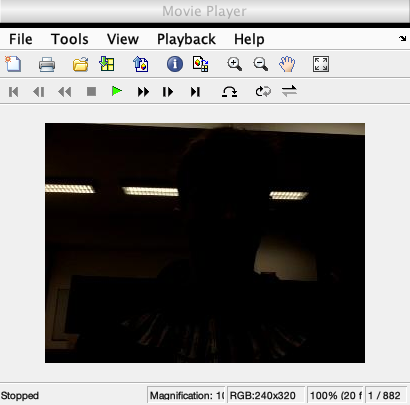

reader = VideoReader(fullFilename);
videoData = read(reader);
implay(videoData);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear v